## Introduction to Symbolic Math Toolbox

For the preparation of V1 of the LAC-MPRA

Autor: Sönke Bartels (sba@tf.uni-kiel.de)

Date:  25.10.2022

Before you start to get into the code-cells make yourself familiar with the three Live-Editor specific tabs ("Live-Editor", "Insert" and "View").

% Text-blocks (like above) can be inserted by pressing the "Text"-button
% in the "Live Editor"-Tab of Matlab
% Here you also find formatting tools for headlines and section-breaks
clc;
clear;

% a command to surpress simplifies output, can be toggled 取消简化输出值
sympref('AbbreviateOutput', false);

### Basics

Using Matlab you commonly surpress outputs by adding a ";" at the line end. Making symbolic calculations you will often need to look at the output. Live-Scripts print the output on the right hand side in a more readable fashion than in the command window.

% Create symbols (this is the same but "syms" can define mutlitple symbols at once)
a = sym("a")

$$a = a$$

syms b c

% Create a time-dependant symbol
% this implicitly defines the symbol t and c as a symbolic function
% (datatype: symfun)
syms d(t)

% Equations
eqn = a + 2*b == -4*c

$$eqn = a+2\,b=-4\,c$$

fprintf("LHS: %s", lhs(eqn)) % access the left-hand-side of an equation

LHS: a + 2*b

fprintf("RHS: %s", rhs(eqn)) % access the right-hand-side of an equation

RHS: -4*c

% '%s' specifies "string or character vector"

### Systems of linear algebraic equations

% Solve and rearrange (make yourself familiar with the difference)
solve(eqn, a)   % this is an expression

$$ans = -2\,b-4\,c$$

eqn_test = isolate(eqn, a) % this is an equation

$$eqn\_test = a=-2\,b-4\,c$$

### Differential equations

% using diff(function, variable) to describe differentiations
syms x(t)
ode = diff(x,t) - x == 0 % ode is an equation: dx/dt -x =0

$$ode(t) = \frac{\partial }{\partial t}x\left(t\right)-x\left(t\right)=0$$

dsolve(ode) % solve a differetial equation

$$ans = C_{1}\,{\mathrm{e}}^{t}$$

### Numeric conversion

% Convert to numeric expression
a_subs = subs(a,a,1)   % still symbolic

$$a\_subs = 1$$

double(a_subs)       % this is a numeric expression 

ans = 1

% sMnew = subs(sM,oldM,newM) returns a copy of sM, replacing all occurrences of oldM with newM, 
% and then evaluates sM. Here, sM is an expression, equation, 
% or condition involving symbolic matrix variables and matrix functions, 
% and oldM specifies the symbolic matrix variables and matrix functions to be substituted. 
eqn_test

$$eqn\_test = a=-2\,b-4\,c$$

eqn_subs = subs(eqn_test,[b,c],[1,2])

$$eqn\_subs = a=-10$$

### Plotting

function that you can use to directly plot symbolic functions with example

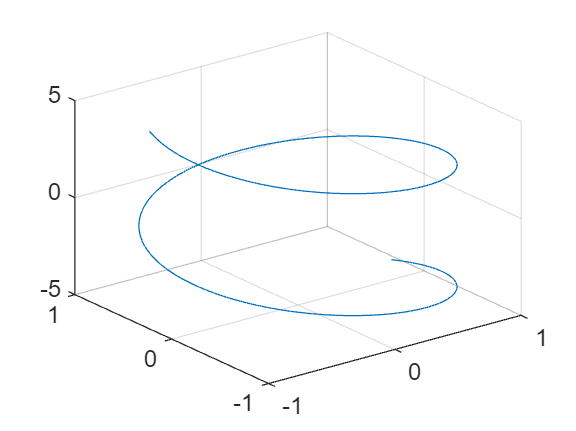

% this is a just a plotting example; remember that "t" is already defined before. ( syms d(t) )
% Of course, there is fplot() for 2-dim plots
% fplot: plot symbolic expression or function
xt = sin(t);
yt = cos(t);
zt = t;
fplot3(xt,yt,zt)

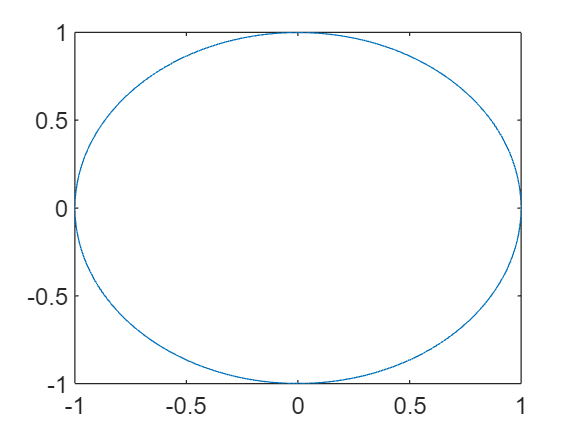

fplot(xt,yt)

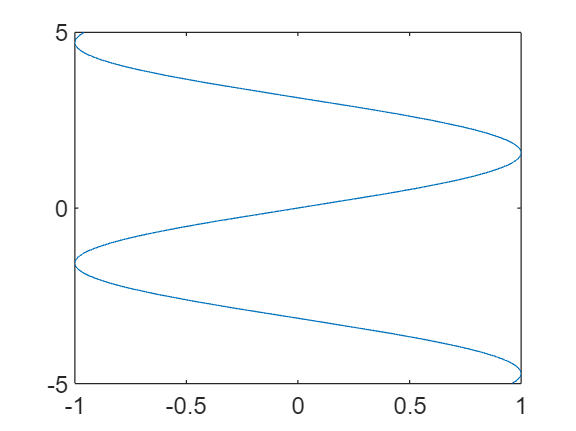

fplot(xt,zt)